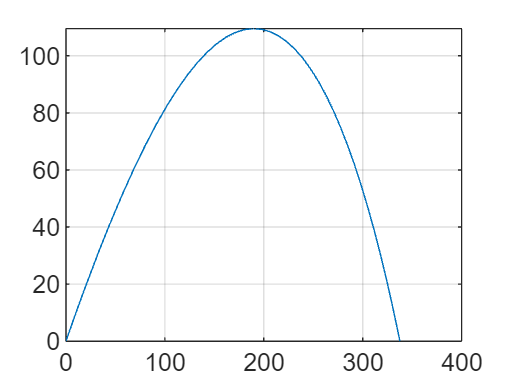

options = odeset('Events', @boden);
[t,u] = ode45(@golf, [0 10], [0 0 0 0 40*sqrt(2) 40*sqrt(2)], options);%[0 10]= Zeitspanne in Sekunden
                                                             %[0 0 0 0] = Anfangsbedingungen (x,y,z,x',y',z')
                                                             %Abschlaggeschwindigkeit v0=80m/s
                                                             %alpha = 45°
                                                             %vy=80*sqrt(2)/2
                                                             %vz=80*sqrt(2)/2
                                                             % rot = y; gelb = z;
                                                             % und violett = x;
                                                             % blau = vz; grün= vy;
plot(u(:,2),u(:,3))  
%plot3(u(:,1),u(:,2),u(:,3)) %erzeugt einen 3dimensionalen Plot
grid on